# **Robot Model**

clear;
clc;
Ts = 0.2;
% Distance to Point P
l = 1;

## MPC Test

% Control Signal
n = 2;
n_u = 2;
t = 0:Ts:20;

% Control Horizon
N = 10;

N_tot = length(t);
u = zeros(n_u, N_tot - N);
x_history = zeros(n, N_tot - N +1);

% Control Matrices
Q = 10*eye(2);
R = 2*eye(2);
P = 12*eye(2);
Y = 3*eye(2);

% Radius of the attraction ball
epsilon = 0.3;

% Robot Parameters
d = 0.5;    % Distance between Wheels [m]
r = 0.25;   % Wheel Radius [m]
robot_params = [d, l, r];

## Simulation Parking

% Initial Pose
x0 = 0;
y0 = 0;
xk = [x0 y0]';
x_history(:,1) = xk;

% Reference Pose
x_P = 5;
y_P = 10;

y_P = 10

poseRef = [x_P*ones(1,N); y_P*ones(1,N)];
thetaRef = 0*ones(1,N);

k = 1;

for i = 1:length(u)
    % Computing the control signals
    u(:,i) = FHOCP2(xk, Q, R, P, Y, N, n, n_u, Ts, poseRef, thetaRef, robot_params);
    % Updating the State
    [xk, yk] = model_Robot_pointP(xk, u(:,i), Ts);
    % States
    x_history(:,i+1) = xk;
end


******************************************************************************
This program contains Ipopt, a library for large-scale nonlinear optimization.
 Ipopt is released as open source code under the Eclipse Public License (EPL).
         For more information visit https://github.com/coin-or/Ipopt
******************************************************************************

Restrictions were met.
Restrictions were met.
Restrictions were met.
Restrictions were met.
Restrictions were met.
Restrictions were met.
Restrictions were met.
Restrictions were met.
Restrictions were met.
Restrictions were met.
Restrictions were met.
Restrictions were met.
Restrictions were met.
Restrictions were met.
Restrictions were met.
Restrictions were met.
Restrictions were met.
Restrictions were met.
Restrictions were met.
Restrictions were met.
Restrictions were met.
Restrictions were met.
Restrictions were met.
Restrictions were met.
Restrictions were met.
Restrictions were met.
Restrictions we

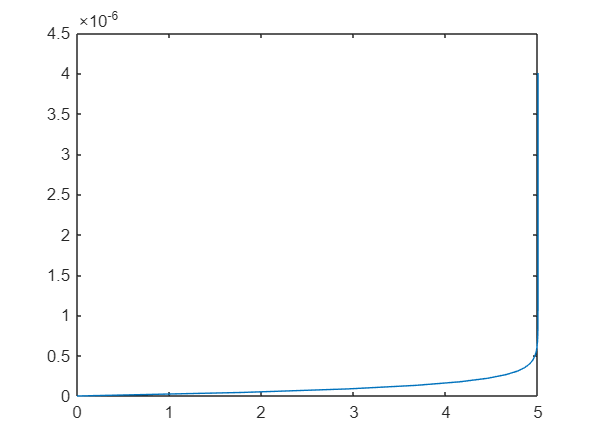

x = x_history(1,:);
y = x_history(2,:);

plot(x,y)